Señal exponencial compleja:

- se crea el vector de tiempo discreto

- se deine el parámetro de amplitud inicial de la señal

- se calculan los valores (amplitud) de cada muestra

- Se grafica la señal

Observe que se trata de una señal exponencial decreciente

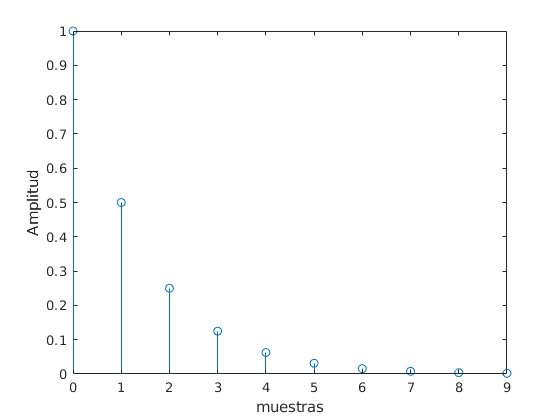

n= 0:9;
A=0.5;
zxn=A.^n;
stem(n,zxn)
xlabel('muestras')
ylabel('Amplitud')

Si se varia el valor del parámetro A, ¿Qué ocurre? Observe que el gráfico cambia de forma a medida que mueve el slider.

A=0.5

A = 0.5000

zxn=A.^n;
stem(n,zxn)
xlabel('muestras')
ylabel('Amplitud')

A continuación se realizará el ejercicio siendo la base de la exponencial un número complejo

zreal =-0.6

zreal = -0.6000

zimag = 0.6

zimag = 0.6000

Se determina la magnitud y el angulo del número complejo

z=zreal+1i*zimag;
magnitud = abs(z)

magnitud = 0.8485

angulo = angle(z) %radianes

angulo = 2.3562

Cálculo de los valores de la función exponencial compleja

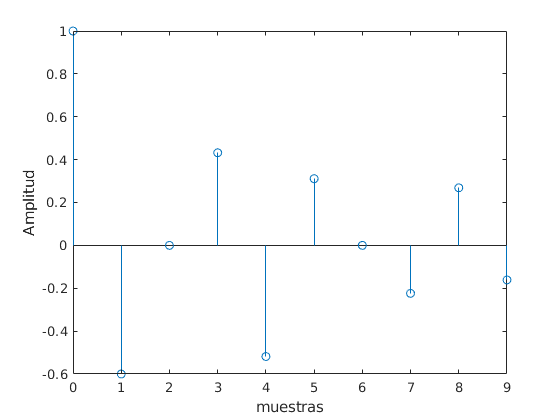

zxn=z.^n;
figure('Name','Parte real')
stem(n,real(zxn))
xlabel('muestras')
ylabel('Amplitud')

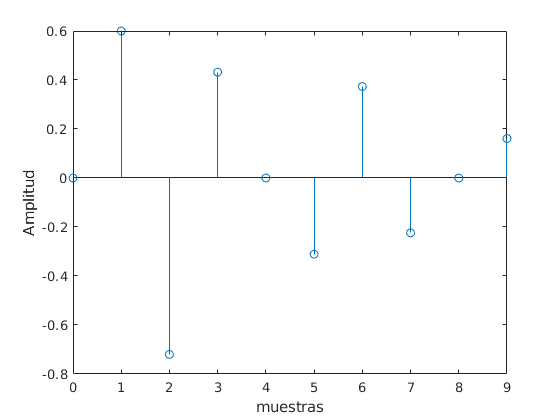

figure('Name','Parte imaginaria')
stem(n,imag(zxn))
xlabel('muestras')
ylabel('Amplitud')

Localización del valor de z en el plano complejo. Observe que relación existe entre esta ubicación y la forma de la función exponencial (debe tener el archivo circulo.m en la misma carpeta de este ejemplo)

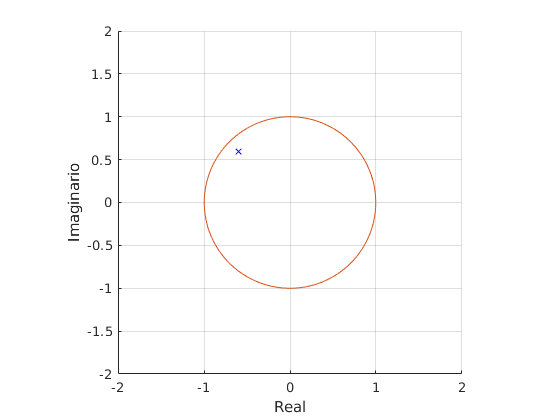


figure
hold on
plot(z,'bx')
circulo(0,0,1)
axis equal
grid on
xlabel('Real')
ylabel('Imaginario')
xlim([-2 2])
ylim([-2 2])
hold off